# Lab - Root Finding 1 - Bracketing

**Topics: **Bisection & fzero

clear, clc, format compact

## Root finding 

### Set up the problem

Determine the mass, *m*, of the bungee jumper with a drag coefficient, $c_d$, of 0.25 to have a velocity of 36 [m/s] after 4 [s] of free fall. The acceleration of gravity, *g*, in SI units is 9.81 [m/s/s]. Given the following function:


$$v\left(t\right)=\sqrt{\frac{\textrm{gm}}{c_d }}\tanh \left(\sqrt{\frac{{\textrm{gc}}_d }{m}}t\right)$$


c_d = .25;
g = 9.81;
v = 36;
t = 4;

f = @(m) sqrt((g*m)/c_d).*tanh(sqrt((g*c_d)./m)*t) - v;

### Find the bounds that contain the root

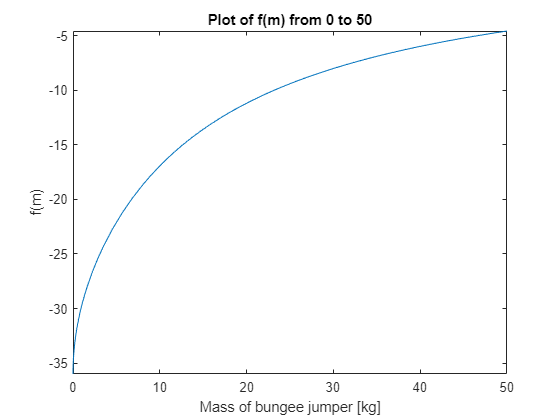

figure()
fplot(f, [0,50])
title("Plot of f(m) from 0 to 50")
xlabel("Mass of bungee jumper [kg]")
ylabel("f(m)")

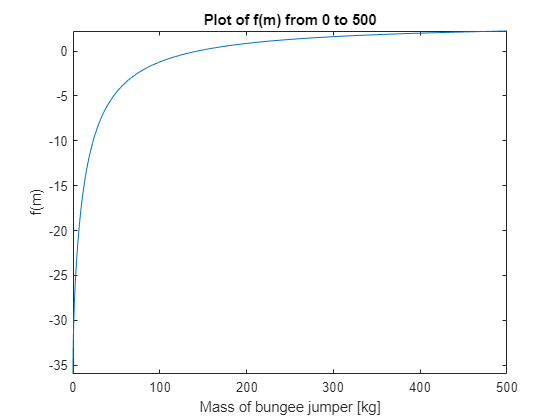

figure()
fplot(f, [0,500])
title("Plot of f(m) from 0 to 500")
xlabel("Mass of bungee jumper [kg]")
ylabel("f(m)")

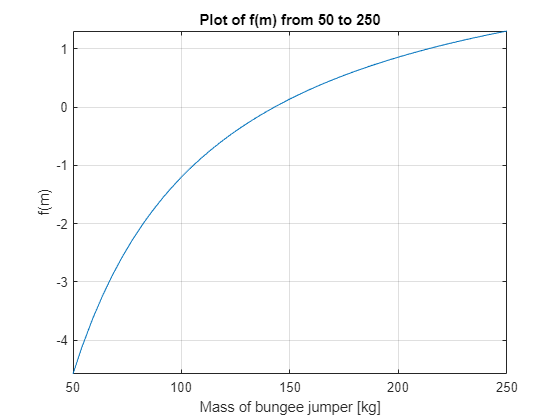

figure()
fplot(f, [50, 250])
title("Plot of f(m) from 50 to 250")
xlabel("Mass of bungee jumper [kg]")
ylabel("f(m)")
grid on

### The root using bisection

m1 = bisect(f,50,250);

fprintf('Using the bisect function \nthe mass of the bungee jumper is %8.4f kg\n', m1)

Using the bisect function 
the mass of the bungee jumper is 142.7377 kg


### The root using fzero

m2 = fzero(f,100);
fprintf('Using Matlab''s fzero function \nthe mass of the bungee jumper is %8.4f kg\n', m2)

Using Matlab's fzero function 
the mass of the bungee jumper is 142.7376 kg


### Verify the roots

f(m1),f(m2)

ans = 8.5105e-07

ans = 0